
T=readtable("Lab6__1.xlsx");

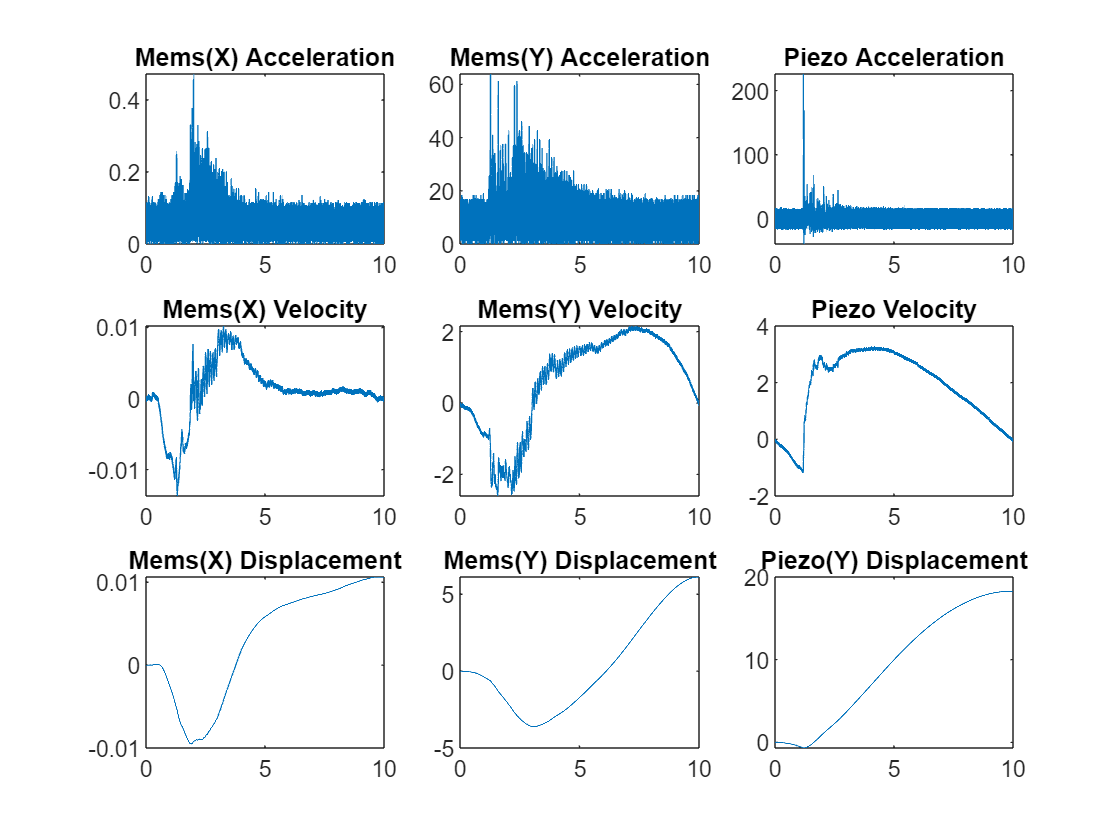

time=0.001:0.001:10;
data=[T(:,2) T(:,4) T(:,6)];
data=table2array(data);
averages=mean(data,1);
[N,M]=size(T);
% 1:mems (x)
% 2:mems (y)
% 3:piezo (y)
CaliMems=300*3.3/3; %mv/g
CaliMems=CaliMems*1/1000/9.81; %V/(m/s^2)
CaliPiezo=10; %mV/g
CaliPiezo=CaliPiezo*1/1000/9.81; %V/(m/s^2)
data_norm=bsxfun(@minus, data , averages);
data_norm(:,3)=data_norm(:,3)/CaliPiezo/2.815;
data_norm(:,1)=data_norm(:,1)/CaliMems; %mems x
data_norm(:,2)=data_norm(:,2)/CaliMems*180; %mems y
X=data_norm(:,3);


V0=fft(data_norm(:,1));
V1=fft(data_norm(:,2));
V2=fft(data_norm(:,3));
Frequency=linspace(0,1000,N);

%Numerical Integration
VelMemX=cumtrapz(time,data_norm(:,1));
VelMemX=VelMemX-VelMemX(1);
VelMemY=cumtrapz(time,data_norm(:,2));
VelMemY=VelMemY-VelMemY(1);
VelPiezoY=cumtrapz(time,X);
VelPiezoY=VelPiezoY-VelPiezoY(1);
disMemX=cumtrapz(time,VelMemX);
disMemX=disMemX-disMemX(1);
disMemY=cumtrapz(time,VelMemY);
disMemY=disMemY-disMemY(1);
disPiezoY=cumtrapz(time,VelPiezoY);
disPiezoY=disPiezoY-disPiezoY(1);

figure(1)
subplot(3,3,1)
plot(time,abs(data_norm(:,1)))
title('Mems(X) Acceleration')
subplot(3,3,2)
plot(time,abs(data_norm(:,2)))
title('Mems(Y) Acceleration')
subplot(3,3,3)
plot(time,X)
title('Piezo Acceleration')

subplot(3,3,4)
plot(time,VelMemX)
title('Mems(X) Velocity')
subplot(3,3,5)
plot(time,VelMemY)
title('Mems(Y) Velocity')
subplot(3,3,6)
plot(time,VelPiezoY)
title('Piezo Velocity')
subplot(3,3,7)
plot(time,disMemX)
title('Mems(X) Displacement')
subplot(3,3,8)
plot(time,disMemY)
title('Mems(Y) Displacement')
subplot(3,3,9)
plot(time,disPiezoY)
title('Piezo(Y) Displacement')


%Frequency Response

Amplitude1=2/N*real(abs(V0));
Amplitude2=2/N*real(abs(V1));
Amplitude3=2/N*real(abs(V2));
% 5 Seconds
figure(2);
subplot(3,2,1)
plot(Frequency(1:N/2),Amplitude1(1:N/2))
title('Mems(X) (5 seconds)')
subplot(3,2,3)
plot(Frequency(1:N/2),Amplitude2(1:N/2))
title('Mems(Y) (5 seconds)')
subplot(3,2,5)
plot(Frequency(1:N/2),Amplitude3(1:N/2))
title('Piezo (5 seconds)')

loc1=Amplitude1==max(Amplitude1(1:N/2));
loc2=Amplitude2==max(Amplitude2(1:N/2));
loc3=Amplitude3==max(Amplitude3(1:N/2));

NaturalFreqV0=Frequency(loc1);
NaturalFreqV1=Frequency(loc2);
NaturalFreqV2=Frequency(loc3);

NaturalFreqV0_5=NaturalFreqV0(1);
NaturalFreqV1_5=NaturalFreqV1(1);
NaturalFreqV2_5=NaturalFreqV2(1);
% Last second
N2=N2/2;
Frequency=linspace(0,1000,N2);
data_norm(1:N2,:)=[];

V0=fft(data_norm(:,1));
V1=fft(data_norm(:,2));
V2=fft(data_norm(:,3));
Amplitude1=2/N2*real(abs(V0));
Amplitude2=2/N2*real(abs(V1));
Amplitude3=2/N2*real(abs(V2));

subplot(3,2,2)
plot(Frequency(1:N2/2),Amplitude1(1:N2/2))

title('Mems(X) (Last second)')
subplot(3,2,4)
plot(Frequency(1:N2/2),Amplitude2(1:N2/2))

title('Mems(Y) (Last second)')
subplot(3,2,6)
plot(Frequency(1:N2/2),Amplitude3(1:N2/2))

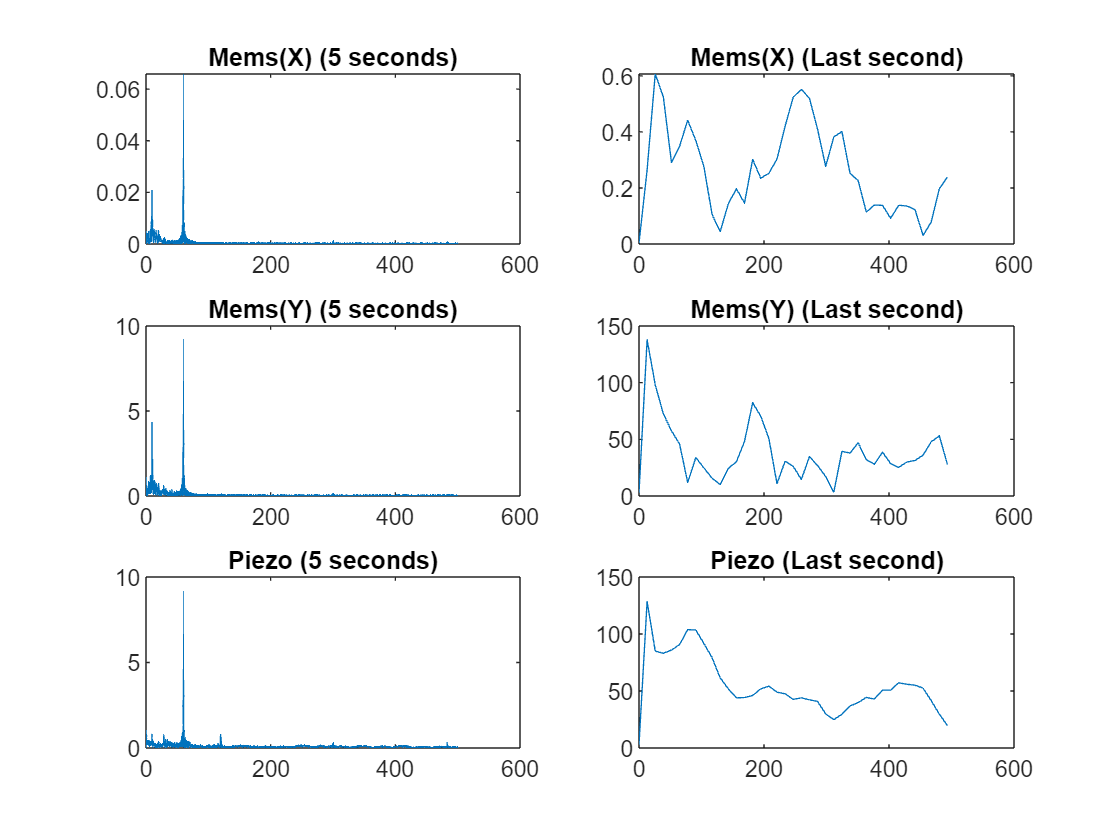

title('Piezo (Last second)')


loc1=find(Amplitude1==max(Amplitude1(1:N2/2)));

loc2=find(Amplitude2==max(Amplitude2(1:N2/2)));

loc3=find(Amplitude3==max(Amplitude3(1:N2/2)));


NaturalFreqV0=Frequency(loc1);

Index exceeds the number of array elements. Index must not exceed 78.

NaturalFreqV1=Frequency(loc2);
NaturalFreqV2=Frequency(loc3);

NaturalFreqV0_Last=NaturalFreqV0(1);
NaturalFreqV1_Last=NaturalFreqV1(1);
NaturalFreqV2_Last=NaturalFreqV2(1);

Frequency_5s=[NaturalFreqV0_5; NaturalFreqV1_5; NaturalFreqV2_5];
Frequency_LastSec=[NaturalFreqV0_Last; NaturalFreqV1_Last; NaturalFreqV2_Last];
Sensor=["Mems(X)";"Mems(Y)";"Piezo(Y)"];
Table=table(Sensor, Frequency_5s, Frequency_LastSec)